% Load the necessary data if not already in the workspace
load('trainingSet.mat'); % XTrain, YTrain
load('validationSet.mat'); % XTest, YTest

% SVM Parameters
t = templateSVM('KernelFunction','polynomial', 'PolynomialOrder',3); % Example: 3rd order polynomial
u = templateSVM('KernelFunction', 'linear')

u = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: 'linear'
               KernelScale: []
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: []
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


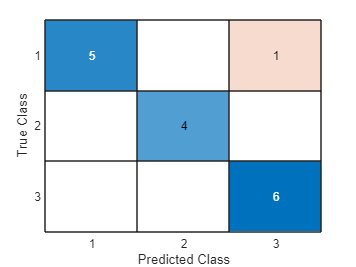

v = templateSVM('KernelFunction','rbf', 'KernelScale', 'auto'); 
svmModel = fitcecoc(XTrain, YTrain, 'Learners', t);
svmModel2 = fitcecoc(XTrain, YTrain, 'Learners', u);
svmModel3 = fitcecoc(XTrain, YTrain, 'Learners', v);


% Predict the labels of the validation set
[YPred, scores] = predict(svmModel, XTest);
[YPred2, scores] = predict(svmModel2, XTest);
[YPred3, scores3] = predict(svmModel3, XTest);

% Convert YPred to categorical if YTest is categorical
YPred = categorical(YPred);

% Evaluate the classifier
confMat = confusionmat(YTest, YPred);
confusionchart(confMat);

accuracy = sum(YTest == YPred) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.9375


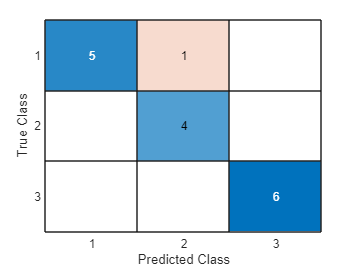


% Evaluate the classifier
confMat = confusionmat(YTest, YPred2);
confusionchart(confMat);

accuracy = sum(YTest == YPred2) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.9375


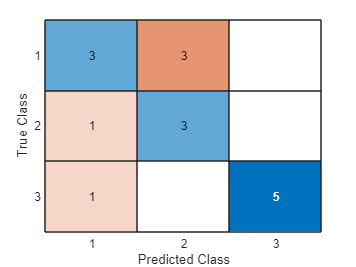


% Evaluate the classifier
confMat = confusionmat(YTest, YPred3);
confusionchart(confMat);

accuracy = sum(YTest == YPred3) / numel(YTest);
disp(['Accuracy: ', num2str(accuracy)]);

Accuracy: 0.6875
